## 1. Estimating a simpel model by simulated minimum distance (SMD)

**Inspiration:** This notebook is based on an example given by Julia/Economics: [https://juliaeconomics.com/tag/method-of-simulated-moments/](https://juliaeconomics.com/tag/method-of-simulated-moments/)

## 2. The economic model

Let $$c_i\geq0$$ denote consumption and $0\le l_i \le 1$ denote leisure. Consider an agent who wishes to maximize Cobb-Douglas utility over consumption and leisure subject to a budget constraint. That is, 

                                                                    
$$\max_{c_i,l_i}c_i^\gamma l_i^{1-\gamma} \\
s.t. \\ 
c_i\leq (1-\tau)w_i(1-l_i)+\epsilon_i$$


where $0\le \gamma \le \;1\;$ is the relative preference for consumption, $w_i$ is wage earned from supplying labor, $\tau \;$ is the tax rate and $\epsilon \;$ is a non-labor income shock.

This model has a closed form solution given by:

                                                        
$$c^\star(w_i,\epsilon_i;\gamma) = \gamma(1-\tau)w_i+\gamma\epsilon_i \\
l^\star(w_i,\epsilon_i;\gamma) = (1-\gamma)+\frac{(1-\gamma)\epsilon_i}{(1-\tau)w_i}$$


## 3. The empirical goal

We will impose a set of simplifying assumptions:

- The unobserved income shock is iid with known distribution, $\epsilon_i \sim N\left(0,\sigma {\;}^2 \right)$.

- The individual wages, $w_i$, are observed along with consumption and labor choices for $n=10,000$ individuals. 

The goal is to estimate the relative preference for consumption and leisure, $\gamma \;$, and the tax rate, $\tau \;\;$ in this model. The set of parameters to be estimated thus is $\theta =\left(\gamma \;,\tau \;,\sigma \;\right)$.

To this end, we asume that we have a dataset consiting of ${\left\lbrace w_i ,c_i ,l_i \right\rbrace }_{i=1}^n$. To simulate such a dataset we run the following code. 

% a. true parameters in the data generating process
par = struct()

par = struct with no fields.


par.gamma = 0.5;
par.tau = 0.2;
par.sigma = 1.0;

% b. simulate observed dataset
rng(2019); % set the seed
n = 10000;

% stochastic variables
w = exp(randn(n,1)); % distribution of log-wages are (arbitrarely) chosen to be standard normal
e = par.sigma*randn(n,1);

% optimal choices
con = model.c_star(w,e,par);
lab = model.l_star(w,e,par);

## 4. Visualizing the data

We could imagine plotting the scatter of consumption and labor supply against wages. 

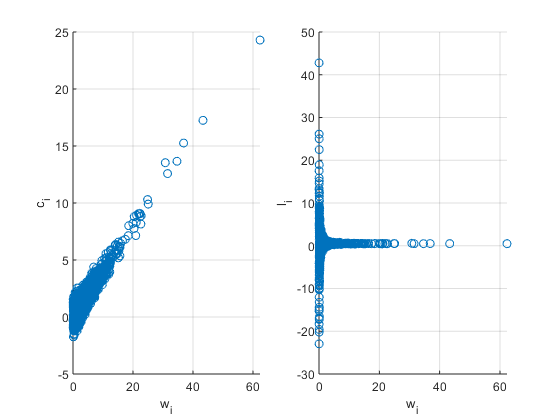

figure(1)
subplot(1,2,1)
scatter(w,con)
grid on
xlabel('w_i')
ylabel('c_i')

subplot(1,2,2)
scatter(w,lab)
grid on
xlabel('w_i')
ylabel('l_i')

We note that there is a clear relationship between consumption and wages. We could thus imagine estimating the two parameters in $\theta \;$ using the correlation between the consumption and wages, the average labor supply and the variance of consumption. 

## 5. Identification

From the solution we note that the correlation between wages and consumption depends on $\gamma \;$ and $\tau \;$, the mean of the labor supply should be $1-\gamma \;$ and that the variance of consumption should be proportional to the variance of $\epsilon \;$, $\sigma {\;}^2$. These moments, in turn, should be able to identify the parameters in $\theta \;$.

We can denote the moments in the data as $\Lambda^{\mathrm{data}} ={\left(\mathrm{corr}\left(w_i ,c_i \right),\mathrm{mean}\left(l_i \right),\mathrm{var}\left(c_i \right)\right)}^{\prime }$ and calculate them as:

moments_fun = @(w,con,lab) [corr(w,con); mean(lab); var(con)];
mom_data = moments_fun(w,con,lab)

mom_data =     0.8734
    0.5052
    1.0443


## 6. A SMD estimator

We can then estimate $\theta \;\;$by minimizing the squared distance between the empirical moments in the data, $\Lambda {\;}^{\mathrm{data}}$, and the same moments calculated from $S=100$ *simulated* agents for each of the $n$ values of $w_i$ from the model for each guess of $\theta \;$, $\Lambda {\;}^{\mathrm{sim}} \left(\theta \;;w\right)$. 

Concretely, we simulate draws of ${\left\lbrace \epsilon {{\;}_i }^{\left(s\right)} \right\rbrace }_{i=1,s=1}^{n,S}$, calculate the synthetic dataset for a value of $\theta \;$, ${\left\lbrace w_i ,c_i^{\left(s\right)} {,l}_i^{\left(s\right)} \right\rbrace }_{i=1,s=1}^{n,s}$, and stack these $n\times S$ observations to calculate the moments above to get $\Lambda {\;}^{\textrm{sim}} \left(\theta \;;w\right)$.

Our **SMD estimator** is     

                                                         
$$\hat{\theta} = \arg \min_\theta Q(\theta;w)$$


where the objective function is $Q(\theta;w)=(\Lambda^{data}-\Lambda^{sim}(\theta;w))'(\Lambda^{data}-\Lambda^{sim}(\theta,w)) $.

The objective function could be coded as done in the `model.obj_fun(). I`n the model.m file. 

## 7. Objective function

We specify which parameters to be estimated and construct initial starting values as

est_par = {'gamma','tau','sigma'}; % parameters to estimate
theta0 = [0.4 , 0.15, 0.9];  % initial guesses

And we can evaluate the objective function as

obj_at_theta0 = model.obj_fun(theta0,est_par,w,mom_data,moments_fun,par)

     1000000           1



mom_sim =     0.9037
    0.5982
    0.7062


obj_at_theta0 = 0.1239

## 8. Call optimizer

We then call an unconstained optimizer using numerical gradients with option to print iterations

options = optimset('Display','iter');
obj_fun = @(theta) model.obj_fun(theta,est_par,w,mom_data,moments_fun,par);
[est,fval] = fminunc(obj_fun,theta0,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.123867                          2.57
     1          16        0.0140409      0.0370448           1.06  
     2          20       0.00315777              1          0.371  
     3          24       0.00147753              1         0.0433  
     4          28       0.00144148              1         0.0254  
     5          32       0.00140566              1         0.0335  
     6          36       0.00124446              1         0.0692  
     7          40      0.000962971              1          0.116  
     8          44      0.000553709              1          0.122  
     9          48      0.000386057              1         0.0707  
    10          52      0.000324113              1         0.0235  
    11          56      0.000311587              1        0.00803  
    12          64      0.000296779             1


% print estimation results
fprintf('\n      True   Est.')


      True   Est.

for p=1:numel(est_par)
    fprintf('%5s %2.3f %2.3f \n',est_par{p},par.(est_par{p}),est(p));
end

gamma 0.500 0.493 
  tau 0.200 0.189 
sigma 1.000 1.010 
